# Mirror position and orientation

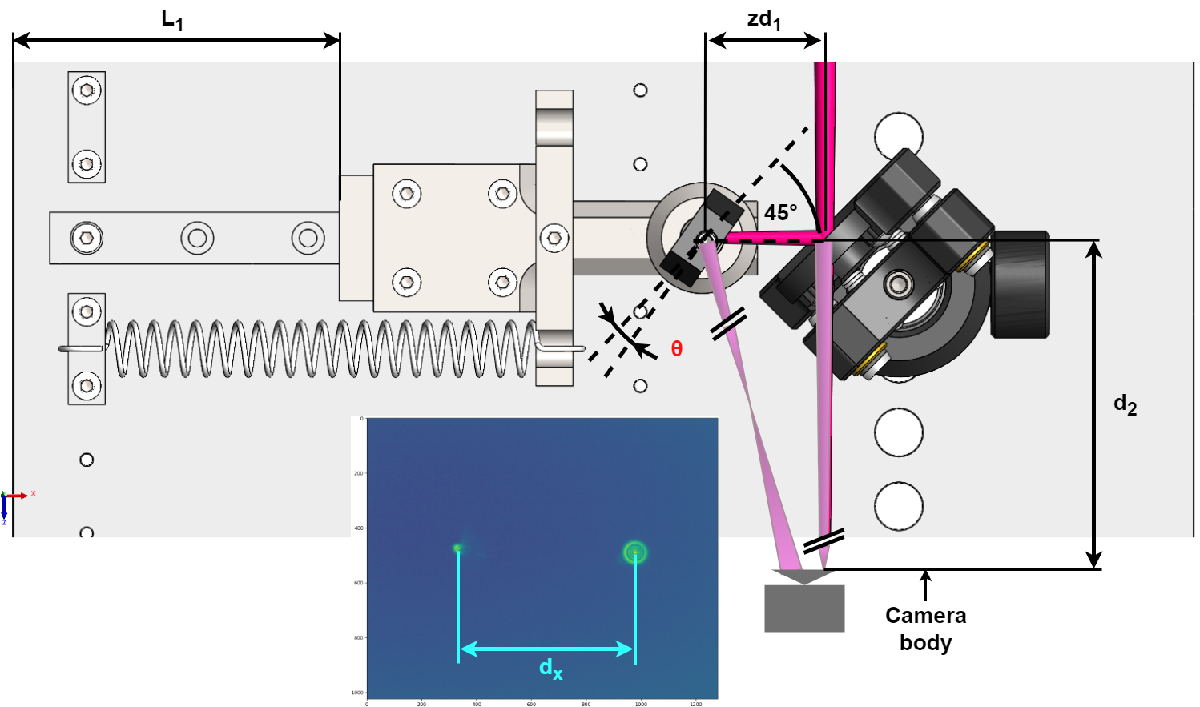

## Input - step 1

F = 25100;    %[mm]
D = 450;      %[mm]
lambda = 900; %[nm]

## Input - step 2

dx = 644*0.0053;     %[mm] effective dist between the two images centers
ddx = 0.0053/2;  %[mm] uncertainety on dx is half a pixel
d2 = 70.2;        %[mm]
dd2 = 1;         %[mm] uncertainety on d2
dL1 = .2;       %[mm] uncertainety on L1


## Calculs

### Step 1

dx_th = 3;  %[mm] default dist between the two images
ximea_sensor_offset = 17.256; %[mm]
carrier_length = 48.5; %[mm]
edge2BS = 110; %[mm]
L1_offset = 13.1; %[mm]
zd1_resting_pos = 48.35; %[mm]

zd_th = 8*(lambda*10^-6)*(F/D)^2; % [mm]
zd1 = (dx_th+zd_th)/2;
L1 = (zd1_resting_pos - zd1) + L1_offset;


### Step 2

zd1 = edge2BS - (L1+carrier_length);
dzd1 = (0.01/edge2BS + dL1/L1 + 0.002/carrier_length)*zd1;

theta = rad2deg(atan((zd1-dx)/(d2+ximea_sensor_offset)));  %[°] default aditional angle

zd2 = tan(deg2rad(theta))*d2;
% zd = zd1 + zd2;    % plus grande incertitude que 2*2*zd1-dx
zd = 2*zd1-dx;

dzd = (dzd1/zd1 + ddx/dx)*zd;


## Output

temptext = sprintf(['---------------------------------------\n' ...
    'Step 1:\n\n' ...
    'Input parameters:\n' ...
    '\tF: %d mm\n' ...
    '\tD: %d mm\n' ...
    '\tlambda: %d nm\n' ...
    'Results:\n' ...
    '\tTheoritical defocus: %.4f mm\n' ...
    '\tL1: %.3f mm\n' ...
    '---------------------------------------\n'],[F,D,lambda,zd_th,L1]);
fprintf(temptext)

---------------------------------------
Step 1:

Input parameters:
	F: 25100 mm
	D: 450 mm
	lambda: 900 nm
Results:
	Theoritical defocus: 22.4004 mm
	L1: 48.750 mm
---------------------------------------



temptext = sprintf(['---------------------------------------\n' ...
    'Step 2:\n\n' ...
    'Input parameters:\n' ...
    '\tdx: %.4f mm\n' ...
    '\tddx: %.5f mm\n' ...
    '\td2: %.2f mm\n' ...
    '\tdd2: %.2f mm\n' ...
    '\tdL1: %.2f mm\n' ...
    'Results:\n' ...
    '\tTheta: %.2f °\n' ...
    '\tEffective zd: %.3f mm\n' ...
    '\tdzd: %.3f mm\n' ...
    '---------------------------------------\n'],[dx,ddx,d2,dd2,dL1,theta,zd,dzd]);
fprintf(temptext)

---------------------------------------
Step 2:

Input parameters:
	dx: 3.4132 mm
	ddx: 0.00265 mm
	d2: 70.20 mm
	dd2: 1.00 mm
	dL1: 0.20 mm
Results:
	Theta: 6.09 °
	Effective zd: 22.087 mm
	dzd: 0.111 mm
---------------------------------------
